# Initialize

img_path = "images/";

## Trading Card Domain

I decided to use images of physical trading cards (e.g. pokemon) as I would like to eventually create an algorithm to separate real and fake cards

figure;
img_pokemon_pika = imread(img_path + "pokemon_pikachu.png");
img_pokemon_pika_g = rgb2gray(img_pokemon_pika);
subplot(1, 3, 1); imshow(img_pokemon_pika); title("original");

img_pokemon_tepig = imread(img_path + "pokemon_tepig.png");

### Segment Card from Background

First we make sure we isolate the card from the rest of the background

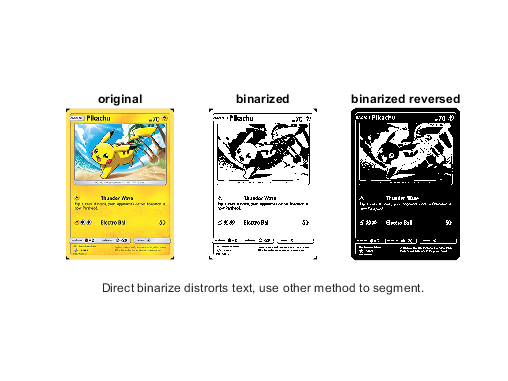

% Use other photo (now card is already isolated)

% Binarize image
img_bw = imbinarize(img_pokemon_pika_g);
img_bw_rev = imcomplement(img_bw);
subplot(1, 3, 2); imshow(img_bw); title("binarized");
xlabel("Direct binarize distrorts text, use other method to segment.");
subplot(1, 3, 3); imshow(img_bw_rev); title("binarized reversed");

### Segment Name

The name of the pokemon will always appear at the top of the card. Therefore, extract all the text possible from the card and retrieve the text on the top-most left area.

#### extract the text from area of interest

figure;

% extract from area of interest
crop_rec = [0.5 0.5 245 34]; % Based on estimated values from imtool

img_cropped = imcrop(img_pokemon_pika, crop_rec);
img_bw_cropped = imcrop(img_bw, crop_rec);

disp("Extracting words using OCR...");

Extracting words using OCR...


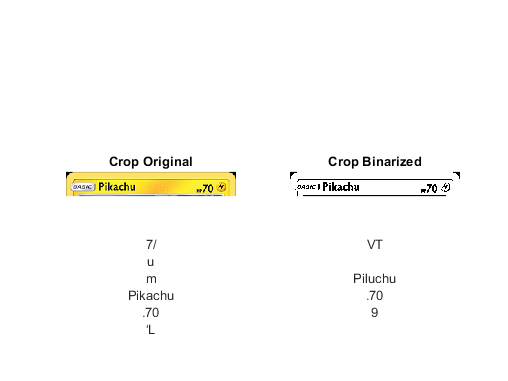

ocr_words = ocr(img_cropped, crop_rec);
ocr_words_bw = ocr(img_bw_cropped, crop_rec);

format_words_rgb = "";
for i=1:size(ocr_words.Words)
    format_words_rgb = format_words_rgb + newline + ocr_words.Words{i};
end

format_words_bw = "";
for i=1:size(ocr_words_bw.Words)
    format_words_bw = format_words_bw + newline + ocr_words_bw.Words{i};
end

subplot(1, 2, 1); imshow(img_cropped); title("Crop Original");
xlabel(format_words_rgb);
subplot(1, 2, 2); imshow(img_bw_cropped); title("Crop Binarized");
xlabel(format_words_bw);


% Region properties
%neighbour_connectivity = 8;
%CC = bwconncomp(img_bw_cropped, neighbour_connectivity)
%S = regionprops(CC,'Centroid')